# Lab Sesión 12

Yimin Pan (G12)

clc;
clear;
I1 = imread("gear.tif");
I2 = imread('rabbit.jpg');

## Experiment 1

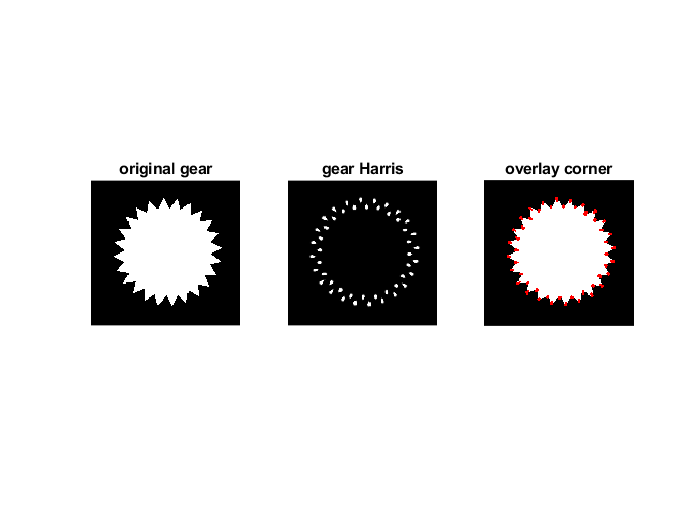

R1 = harris(I1);
corners = im2bw(R1); % binary image
ImRes = imoverlay(I1,corners,[1 0 0]);
figure; subplot(1,3,1); imshow(I1); title('original gear');
subplot(1,3,2); imshow(R1); title('gear Harris');
subplot(1,3,3); imshow(ImRes); title('overlay corner');

## Experiment 2

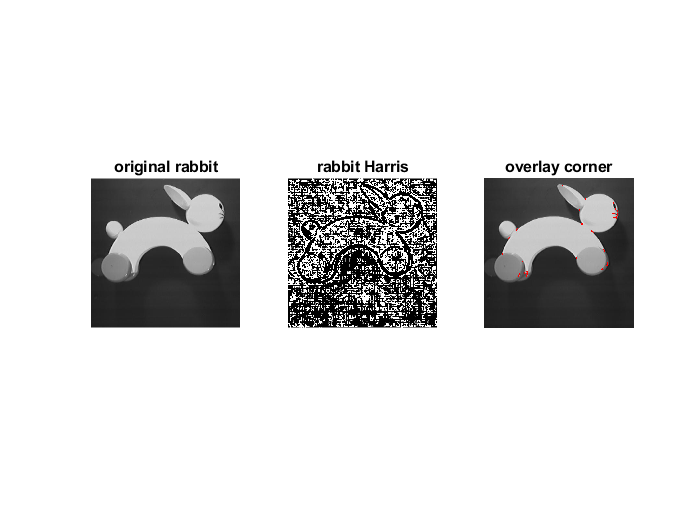

[n m] = size(I2);
R2 = harris(I2);    % points with higher values means its a corner
weight = 0.001; % lower means we mark more point as corner (can be tuned)
th = weight*max(max(R2));
corners = zeros([n m]);
% mark as corner if the value is greater than th
for i = 1:n
    for j = 1:m
        if (R2(i,j) > th) 
            corners(i,j) = 1;
        end
    end
end
ImRes = imoverlay(I2,corners,[1 0 0]);
figure; subplot(1,3,1); imshow(I2); title('original rabbit');
subplot(1,3,2); imshow(R2); title('rabbit Harris');
subplot(1,3,3); imshow(ImRes); title("overlay corner"); 

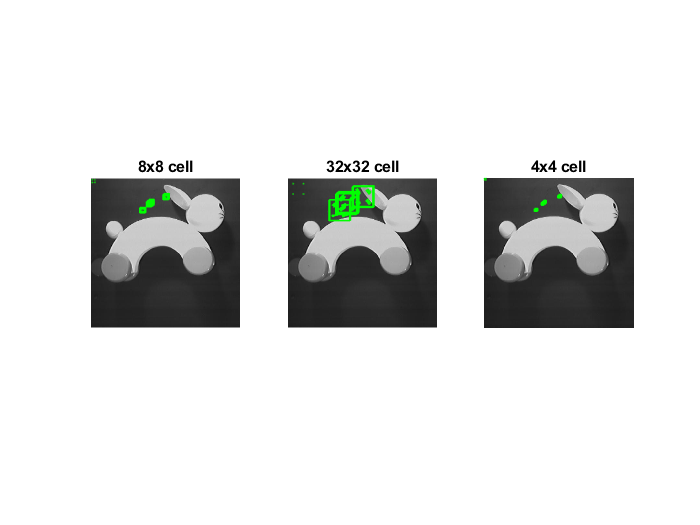



% Histogram of orientation
% still too much points, we select some for the plot
[rows, cols] = find(corners);
points = [rows cols];
selected = points(1:50,:);
[hog, validPoints, ptVis] = extractHOGFeatures(I2,selected,'CellSize',[8 8]); 
figure; subplot(1,3,1); imshow(I2); hold on; plot(ptVis,'Color','green'); title("8x8 cell");
[hog2, validPoints2, ptVis2] = extractHOGFeatures(I2,selected, 'CellSize',[32 32]); 
subplot(1,3,2); imshow(I2); hold on; plot(ptVis2,'Color','green'); title("32x32 cell");
[hog3, validPoints3, ptVis3] = extractHOGFeatures(I2,selected, 'CellSize',[4 4]); 
subplot(1,3,3); imshow(I2); hold on; plot(ptVis3,'Color','green'); title("4x4 cell");

The features of the points are in the hogx variables.

function R = harris(I)
    [Ix Iy] = imgradientxy(I,'sobel');  % partial derivative with sobel
    g = fspecial('gaussian',3,2); % gaussian filter of size 5 and std 2
    Ix = imfilter(Ix, g);
    Iy = imfilter(Iy, g);
    Ix2 = imfilter(Ix.^2, g);
    Iy2 = imfilter(Iy.^2, g);
    Ixy = imfilter(Ix.*Iy, g);
    k = 0.04;
    R = (Ix2.*Iy2-(Ixy.^2)) -k*((Ix2+Iy2).^2); % apply formula
end